%国家类型判别的BP网络（变量除以平均值）
clear                                       %清理内存
P=[1.0777  1.0464  1.0900  1.0723  0.9960  1.0219  1.0328  0.9088  0.9715  0.9633  0.9933  0.9510  0.9456	0.9088 
1.0784 	1.0784 	1.0784 	1.0784 	1.0533 	0.8126 	1.0500 	1.0838 	1.0697 	0.9934 	1.0784 	1.0108 	0.8474 	0.5849 
2.0117 	2.5255 	1.9840 	2.1763 	1.0248 	1.5116 	0.3384 	0.5511 	0.4102 	0.5124 	0.2860 	0.3658 	0.3443 	0.2594]; 
                                            %输入变量
T=[1 1 1 1 1 1 0 0 0 0 0 0 0 0];            %目标输出
net=newff(minmax(P),[2,3,1],{'logsig','tansig','purelin'},'trainlm');

          See help for NEWFF to update calls to the new argument list.
 


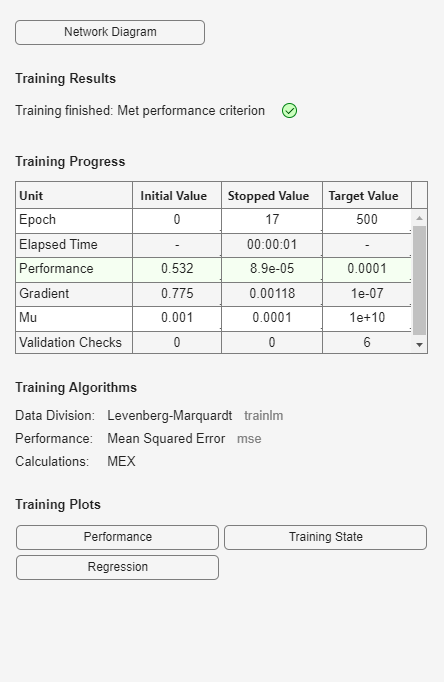

                                            %创建一个隐含层包括6个神经元的BP网络
net.trainParam.epochs=500;                  %最大学习次数500次
net.trainParam.goal=0.0001;                 %训练误差0.0001，小于次数可以终止学习
net=train(net,P,T);                         %训练网络

Y=sim(net,P);Y                              %训练样本的仿真结果

Y =     1.0056    0.9909    1.0058    0.9988    0.9947    1.0040   -0.0028    0.0199   -0.0026    0.0177   -0.0159   -0.0035    0.0011   -0.0079


P_test=[1.0723 	1.0655 	0.9565 	0.9265 
1.0784 	1.0555 	1.0664 	0.9019 
1.7624 	1.1894 	0.4818 	0.2649];            %输入待判样品信号
Yt=sim(net,P_test);Yt                       %待判样品的仿真结果

Yt =     1.0251    1.1244    0.0090    0.0007
